# Demonstration of aggregation of constraints in a topopt problem

## Simone Coniglio - Joseph Morlier 

## Introduction

In this guided work you will discover stress based constraint in structural and topology optimization. If you are interested in further deatails you can refear to [1-2].

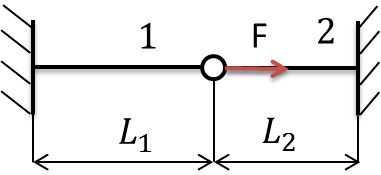

In this exercice we want to show you the issues related to stress based constraint. 

In the above system the bar 1 and 2  are defined by their lenght $L_i 
$, cross section area $A_i$ and material properties $E_i, \nu_i, \rho_i, \sigma_{li}$. 

Let's consider the following setting of parameters:


$$E_1 = 210GPa \quad,\quad  E_2 = 70GPa \\
\rho_1 = 7800 \frac{Kg}{m^3} \quad,\quad \rho_2 = 2700 \frac{Kg}{m^3}\\
L_1 = 2m \quad,\quad L_2=1.75m\\
\sigma_{l1}=800MPa  \quad,\quad \sigma_{l2}=200MPa $$


And the force applied to the system is $\|\vec{F}\|=10000N$is applied in the axial direction. The stress based optimization we want to address is the minimization of the total truss mass with respect to the cross section areas $(A_1, A_2)$. In order to get a fesible final design the Von Mises stress in each bar should be smaller than the allowable  stress limit i.e. $\sigma_1$ and $\sigma_2$ respectively.  The constraint should not be active when the relative component is vanished ($A_i=0$ for this reason this problem is also called a vanishing constraint problem). Finally the problem can be stated as:


$$\min_{(A_1,A_2)}(\rho_1A_1L_1+\rho_2A_2L_2)\\
s.t.\\
g_1(A_1,A_2)=\frac{|\sigma_1|}{\sigma_{l1}}-1\leq 0 \quad \forall A_1>0\\
g_2(A_1,A_2)=\frac{|\sigma_2|}{\sigma_{l2}}-1\leq 0\quad \forall A_2>0\\
0\leq A_1 \leq 100 \quad 0\leq A_2 \leq 100 $$


The normal stress inside each bar can be found using the knowledge of both bar stiffness in function of their properties $\left(K_i=\frac{E_iA_i}{L_i}\right)$ and the fact that the axial displacement of the Force application point is the same in both bar than:


$$\begin{array}{l}
\sigma_1 =\frac{E_1 {FL}_2 }{{E_1 A}_1 L_2 +{E_2 A}_2 L_1 }\\
\sigma_2 =-\frac{E_2 {FL}_1 }{{E_1 A}_1 L_2 +E_2 A_2 L_1 }
\end{array}$$


The existence of both constraints will impose that both cross sections cannot simultaneously be equal to 0. $(A_1,A_2)\neq(0,0)$.

**1a) Explore the design space:**

Plot the design space in matlab using appropriately meshgrid and contour functions. Refer to Matlab help.

By graphical inspection which is the global minima?

**Solution**

Input parameters:

E_1=210000; %MPa
E_2=70000; %MPa
L_1=2000; %mm
L_2=1750; %mm
sl_1= 800; %MPa
sl_2= 200; %MPa
rho_1=7.8e-3; %g/mm^3
rho_2=2.7e-3; %g/mm^3
F=10000; %N

Then generate a grid of value of $A_1$ and $A_2$ using meshgrid function

A_1=0:0.1:100; %mm^2
A_2=0:0.1:100; %mm^2
[A_1,A_2]=meshgrid(A_1,A_2);

generate the corresponding value of constraints and objective function.

s_1=E_1*F*L_2./(E_1*A_1*L_2+E_2*A_2*L_1); %MPa
s_2=-E_2*F*L_1./(A_1*L_2*E_1+A_2*L_1*E_2); %MPa
g_1=(abs(s_1)/sl_1-1).*(A_1>0);
g_2=(abs(s_2)/sl_2-1).*(A_2>0);
o=rho_1*L_1*A_1+rho_2*L_2*A_2; %g

Plot a contour isovalue for each constraint equal to 0, and tha add also some isovalues for the objective function

figure
contour(A_1,A_2,g_1,[0 0],'r','LineWidth',2)
hold on
contour(A_1,A_2,g_2,[0 0],'b','LineWidth',2)
contour(A_1,A_2,o,'LineWidth',2) 
colorbar
xlabel('A_1 [mm^2]')
ylabel('A_2 [mm^2]')
legend('g_1(A_1,A_2)=0','g_2(A_1,A_2)=0','o(A_1,A_2) contour plot')
plot([0,50],[0,0],'b','LineWidth',2)
plot([0,0],[0,75],'r','LineWidth',2)

Define the point A ,B and C as:


$$A = (0,a) \quad s.t. \quad g_2(0,a)=0\\
B=(b,0) \quad s.t. \quad g_2(b,0)=0\\
C=(c,0)\quad s.t. \quad g_1(c,0)=0\\$$


so that:


$$a=\frac{F}{\sigma_{l2}};b=\frac{E_2L_1}{E_1L_2}a;c=\frac{F}{\sigma_{l1}}$$


By graphical insepection one can found that the global minimum is in C with a mass of $m_c=\rho_1L_1\frac{F}{\sigma_{l1}}$.

The optimization problem ha a local minimum in A with a mass of $m_a=\rho_2L_2\frac{F}{\sigma_{l2}}$ 

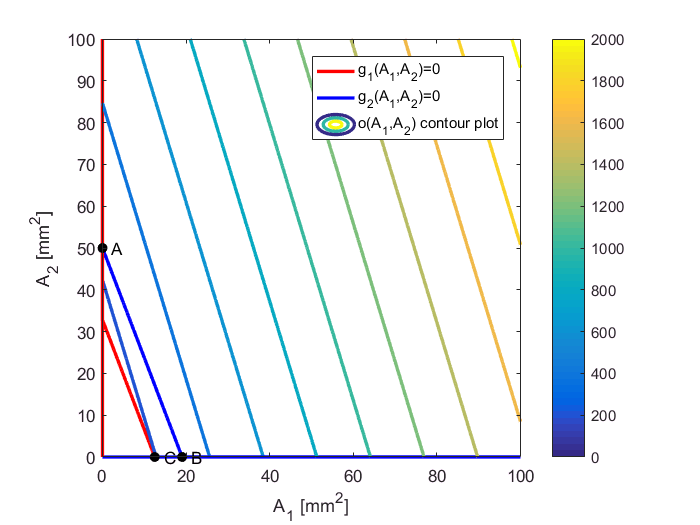

a=F/sl_2;b=a*E_2*L_1/E_1/L_2;
c=F/sl_1;
scatter(0,a,'filled','k')
scatter(b,0,'filled','k')
scatter(c,0,'filled','k')
text(0,a,'  A')
text(b,0,'  B')
text(c,0,'  C')
axis equal

m_c=rho_1*L_1*F/sl_1

m_c = 195

m_a=rho_2*L_2*F/sl_2

m_a = 236.2500

**1b) Evaluate constraint and objective function gradients:**

**Solution**

Using the definition of o, $g_1$ and $g_2$ one can get


$$\vec{\nabla o}=\lbrace\rho_1L_1 ,\rho_2L_2\rbrace^T\\

\vec{\nabla g_1}=\left\lbrace\frac{-E_1^2FL_2^2}{(E_1A_1L_2+E_2A_2L_1)^2\sigma_{l1}},\frac{-FL_2L_1E_2E_1}{(A_1L_2E_1+A_2L_1E_2)^2\sigma_{l1}}\right\rbrace^T \quad \forall A_1>0\\
\vec{\nabla g_2}=\left\lbrace\frac{-FL_2L_1E_2E_1}{(A_1L_2E_1+A_2L_1E_2)^2\sigma_{l2}},\frac{-E_2^2FL_1^2}{(E_1A_1L_2+E_2A_2L_1)^2\sigma_{l2}}\right\rbrace^T \quad \forall A_2>0\\$$


Must  be noted that $g_1$ and $g_2$ are not continuos function respectively for $A_1=0$ and for $A_2=0$. For the same reason the gradient is not defined in the same region. 

to display the objective gradient use the function quiver.

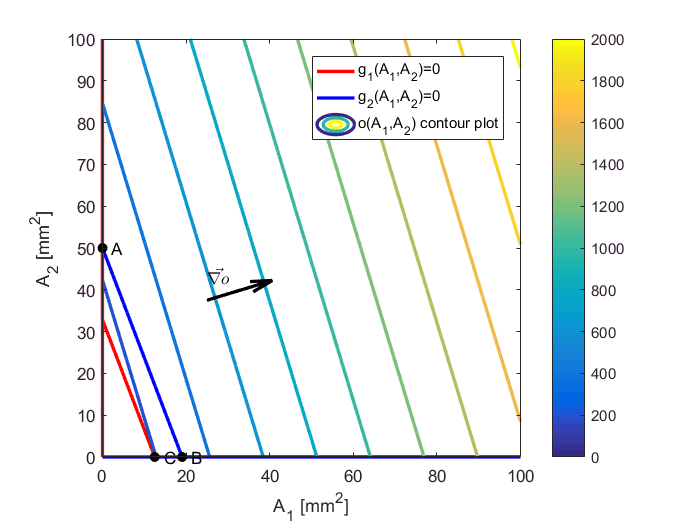

quiver(25,75/2,rho_1*L_1,rho_2*L_2,0,'k','LineWidth',2,'MaxHeadSize',1)
axis equal
text(25,75/2+5,'$\vec{\nabla o}$','Interpreter','latex')

**1c)  Solve numerically the optimization problem:**

Use fmincon to find the constrained optimization problem, to reduce the optimization elapsed time try also to supply objective gradient. Check gradient accuracy by finite difference refer to check gradient option in fmincon. Try more initial points as starting guess. Which minimum did you find, is it the global minimum?

**Solution**

In order to use fmincon we must define constraints function that we call during the optimization procedure. Follow Matlab help to create objective and constriaint function.

options = optimoptions('fmincon','Display','iter','SpecifyObjectiveGradient',true);
[xmin]=fmincon(@(x) mass_truss(x),[35,50],[],[],[],[],[0 0],[50 75],...

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    7.822500e+02    0.000e+00    1.559e+01
    1       6    5.189622e+02    0.000e+00    1.552e+01    1.615e+01
    2       9    1.876325e+02    2.612e-01    1.533e+01    2.033e+01
    3      12    1.856735e+02    2.724e-01    4.551e+00    1.350e-01
    4      15    1.651272e+02    4.307e-01    3.115e+00    4.351e+00
    5      18    2.148719e+02    9.962e-02    3.517e+00    1.051e+01
    6      21    2.345353e+02    7.689e-03    9.836e-02    4.097e+00
    7      24    2.361847e+02    2.880e-04    2.295e-02    4.379e-01
    8      27    2.362504e+02    0.000e+00    2.000e-04    1.655e-02
    9      30    2.362500e+02    0.000e+00    4.825e-06    1.370e-04

Local minimum found that satisfies the constraints.

Optimizati

xmin =     0.0000   50.0000


    @(x) stress_constraints(x),options)

 The solver find the local minimum A and not the global minimum C. It's a classic problem of vanishing constraint optimization problem, as the global optimum  belongs to a reduced dimension subspace included in the desing space (in this case the line $A_2=0$) the global optimum is not achievable by a classic gradient base optimization procedure used by fmincon.

**1d) Use an **$\epsilon$**- relaxation technique to modify the initial problem**

This is a very well known [3] relaxation technique that consist in accepting a small constraint violation for each constraint:

We multiply each constraint by the corresponding adimmensional variable  $\frac{A_i}{\max(A_i)}  $:


$$\bar{g}_1=\frac{A_1}{\max(A_1)}g_1-\epsilon \quad \forall A_1 \\
\bar{g}_2=\frac{A_2}{\max(A_2)}g_2-\epsilon  \quad \forall A_2$$


The final allowable design is modfy consequently and the global minimum is then reachable using gradient base techniques.

Test the effect of $\epsilon$ on the feasible design.

**Solution**

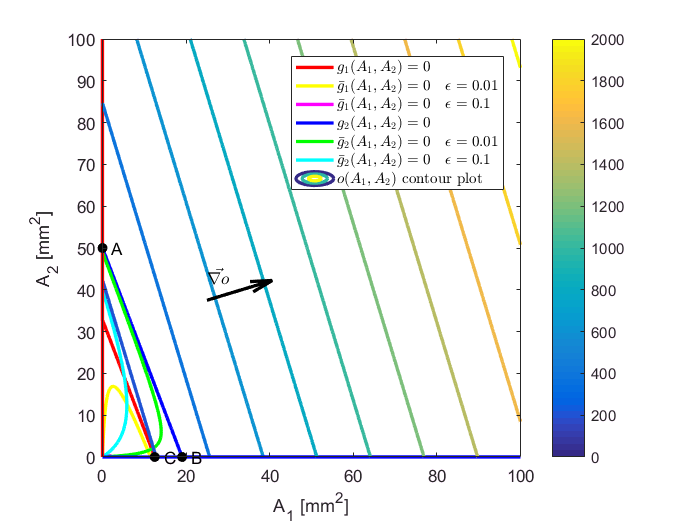

barg_1001=(abs(s_1)/sl_1-1).*(A_1/100)-0.01;
barg_2001=(abs(s_2)/sl_2-1).*(A_2/100)-0.01;
barg_101=(abs(s_1)/sl_1-1).*(A_1/100)-0.1;
barg_201=(abs(s_2)/sl_2-1).*(A_2/100)-0.1;

figure
contour(A_1,A_2,g_1,[0 0],'r','LineWidth',2)
hold on
contour(A_1,A_2,barg_1001,[0 0],'y','LineWidth',2)
contour(A_1,A_2,barg_101,[0 0],'m','LineWidth',2)

contour(A_1,A_2,g_2,[0 0],'b','LineWidth',2)
contour(A_1,A_2,barg_2001,[0 0],'g','LineWidth',2)
contour(A_1,A_2,barg_201,[0 0],'c','LineWidth',2)

contour(A_1,A_2,o,'LineWidth',2) 
colorbar
xlabel('A_1 [mm^2]')
ylabel('A_2 [mm^2]')
legend({'$g_1(A_1,A_2)=0$','$\bar{g}_1(A_1,A_2)=0 \quad\epsilon =0.01$',...
    '$\bar{g}_1(A_1,A_2)=0 \quad\epsilon =0.1$','$g_2(A_1,A_2)=0$',...
    '$\bar{g}_2(A_1,A_2)=0\quad \epsilon =0.01$','$\bar{g}_2(A_1,A_2)=0 \quad \epsilon =0.1$','$o(A_1,A_2)$ contour plot'}...
    ,'Interpreter','latex')
plot([0,50],[0,0],'b','LineWidth',2)
plot([0,0],[0,75],'r','LineWidth',2)
scatter(0,a,'filled','k')
scatter(b,0,'filled','k')
scatter(c,0,'filled','k')
text(0,a,'  A')
text(b,0,'  B')
text(c,0,'  C')
quiver(25,75/2,rho_1*L_1,rho_2*L_2,0,'k','LineWidth',2,'MaxHeadSize',1)
axis equal
text(25,75/2+5,'$\vec{\nabla o}$','Interpreter','latex')

The constraint obtained in this way belongs to$\mathbf{C}^{\infty}$ moreover naturally satisfy the vanishing condition for both $A_1=0$ and $A_2=0$.

**1e) Aggregate constraint**

In order to get advantage from the use of adjoint approach for constraint gradient evaluation one may want to limit the number of constraint in the final optimization problem. In order to do so, one may impose that an aggregate constraint defined as:


$$G_{max}=\max(\bar{g}_1,\bar{g}_2)\leq=0$$


that is also equivalent to ask that both constraints have to be less than or equal to 0.

A problem coming from this formulation is the fact that the $\max$ function, is not differentiable by it's argument, and this can produce several convergence issues. A continuos approximation should on the other hand be used.

Several function can be found in literature that approximate the maximum function, here we use the *Kreisselmeir-Steinhauser *function  [4]  (KS-function hereafter):


$$G_{KS}=\frac{1}{P}\ln\left(\sum_{i=1}^{N}e^{P\bar{g}_i}\right)$$


Where P is an hyperparameter of the KS-function, the greater it is the smaller is the difference between the KS-function and the maximum function.

Test  the influence of the P parameter over the feasible domain. Keep $\epsilon = 0.01$.

**Solution**

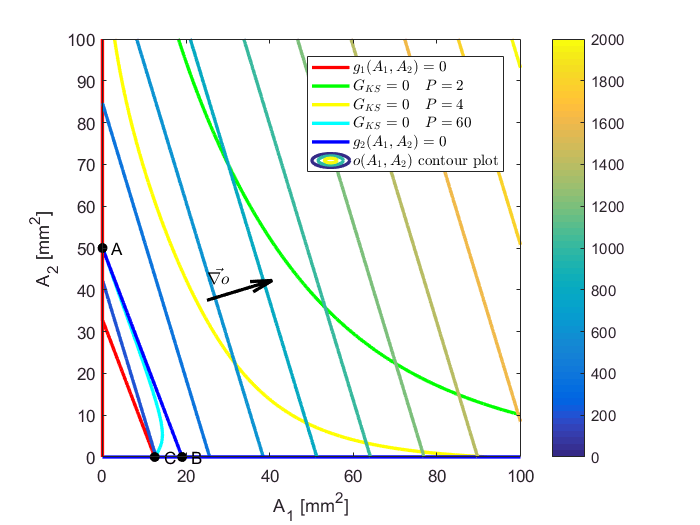

P=2;
G_ks_2=1/P*log((exp(P*(barg_1001))+exp(P*(barg_2001))));
P=4;
G_ks_4=1/P*log((exp(P*(barg_1001))+exp(P*(barg_2001))));
P=60;
G_ks_6=1/P*log((exp(P*(barg_1001))+exp(P*(barg_2001))));
figure
contour(A_1,A_2,g_1,[0 0],'r','LineWidth',2)
hold on
contour(A_1,A_2,G_ks_2,[0 0],'g','LineWidth',2)
contour(A_1,A_2,G_ks_4,[0 0],'y','LineWidth',2)
contour(A_1,A_2,G_ks_6,[0 0],'c','LineWidth',2)
contour(A_1,A_2,g_2,[0 0],'b','LineWidth',2)
contour(A_1,A_2,o,'LineWidth',2) 
colorbar
xlabel('A_1 [mm^2]')
ylabel('A_2 [mm^2]')
legend({'$g_1(A_1,A_2)=0$','$G_{KS}=0 \quad P=2$',...
    '$G_{KS}=0 \quad P=4$','$G_{KS}=0 \quad P=60$','$g_2(A_1,A_2)=0$',...
    '$o(A_1,A_2)$ contour plot'},'Interpreter','latex')
plot([0,50],[0,0],'b','LineWidth',2)
plot([0,0],[0,75],'r','LineWidth',2)
scatter(0,a,'filled','k')
scatter(b,0,'filled','k')
scatter(c,0,'filled','k')
text(0,a,'  A')
text(b,0,'  B')
text(c,0,'  C')
quiver(25,75/2,rho_1*L_1,rho_2*L_2,0,'k','LineWidth',2,'MaxHeadSize',1)
axis equal
text(25,75/2+5,'$\vec{\nabla o}$','Interpreter','latex')

Finally solve the optimization problem for each value of P of the KS function. What can we conclude?

[xmin_P2]=fmincon(@(x) mass_truss(x),[35,35],[],[],[],[],[0 0],[50 75],...

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    7.113750e+02    1.014e-01    1.552e+01
    1       6    6.282296e+02    1.368e-01    1.537e+01    5.101e+00
    2       9    6.301550e+02    1.359e-01    3.363e+00    1.294e-01
    3      12    8.736626e+02    0.000e+00    3.639e+00    2.149e+01
    4      15    8.084245e+02    4.743e-03    2.776e+00    1.358e+01
    5      18    7.736284e+02    6.299e-03    2.049e+00    1.227e+01
    6      21    7.746080e+02    5.781e-03    1.965e-02    7.164e-02
    7      24    7.869655e+02    4.525e-06    8.801e-03    7.948e-01
    8      27    7.869551e+02    0.000e+00    6.632e-05    9.342e-03
    9      30    7.869548e+02    0.000e+00    8.611e-07    7.767e-05

Local minimum found that satisfies the constraints.

Optimizati

xmin_P2 =    27.7295   75.0000


    @(x) aggregated_relaxed_stress_constraints(x,2,0.01),options)
[xmin_P4]=fmincon(@(x) mass_truss(x),[35,35],[],[],[],[],[0 0],[50 75],...

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    7.113750e+02    0.000e+00    1.552e+01
    1       6    5.211841e+02    1.148e-02    1.543e+01    1.167e+01
    2       9    5.202275e+02    1.188e-02    2.609e+00    6.417e-02
    3      12    5.251504e+02    5.062e-04    2.408e+00    6.036e+00
    4      15    4.807069e+02    6.716e-03    1.525e+00    1.598e+01
    5      18    4.697919e+02    5.945e-03    6.001e-01    1.783e+01
    6      21    4.810503e+02    3.546e-05    4.096e-02    1.143e+00
    7      24    4.811149e+02    5.886e-07    6.795e-03    1.966e-01
    8      27    4.811161e+02    0.000e+00    7.053e-05    5.260e-02
    9      30    4.811160e+02    0.000e+00    7.252e-07    4.963e-04

Local minimum found that satisfies the constraints.

Optimizati

xmin_P4 =     9.7978   69.4753


    @(x) aggregated_relaxed_stress_constraints(x,4,0.01),options)
[xmin_P6]=fmincon(@(x) mass_truss(x),[35,35],[],[],[],[],[0 0],[50 75],...

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    7.113750e+02    0.000e+00    1.558e+01
    1       6    4.481476e+02    0.000e+00    1.552e+01    1.615e+01
    2       9    1.741849e+02    1.040e-01    1.520e+01    1.681e+01
    3      13    1.744118e+02    1.036e-01    1.002e+01    1.656e-02
    4      16    1.957398e+02    6.103e-02    7.943e+00    5.747e+00
    5      19    1.895532e+02    3.602e-03    1.187e+01    2.114e+01
    6      23    1.893750e+02    3.558e-03    9.714e+00    5.100e-02
    7      26    1.928244e+02    2.265e-03    4.170e-01    2.420e-01
    8      29    1.996331e+02    1.408e-04    3.318e-01    4.356e-01
    9      32    2.001301e+02    0.000e+00    8.278e-03    3.206e-02
   10      35    2.000931e+02    0.000e+00    2.415e-03    2.909e-03
   11      38    2.000926e+02    0.000e+00    3.594e-06    3.499e-05



xmin_P6 =    12.8265    0.0000


    @(x) aggregated_relaxed_stress_constraints(x,60,0.01),options)

The difficulties here is to tune up the two hyperparameters in order to get the real global minimum in a limited number of iteration.

We can also note that the real maximum 

[c,0]

ans =    12.5000         0


Is not achieved. Feasible point found are much too conservatives!

**1f) Use a unified approach**

We will use the unified approach introduced in [1] relax the initial problem as follows:

We multiply each constraint by the corresponding adimmensional variable  $\frac{A_i}{\max(A_i)}  $:


$$\bar{g}_1=\frac{A_1}{\max(A_1)}g_1 \quad \forall A_1 \\
\bar{g}_2=\frac{A_2}{\max(A_2)}g_2 \quad \forall A_2$$


Still the epsilon relaxation in this method is not applied and the constraint aggregation is directly applied. Again we considered the *lower bound KS-function [1]*:


$$G_{KS}^l=\frac{1}{P}\ln\left(\frac{1}{N}\sum_{i=1}^{N}e^{P\bar{g}_i}\right)$$


Again investigate the behavior of the feasible domain with P.

**Solution**

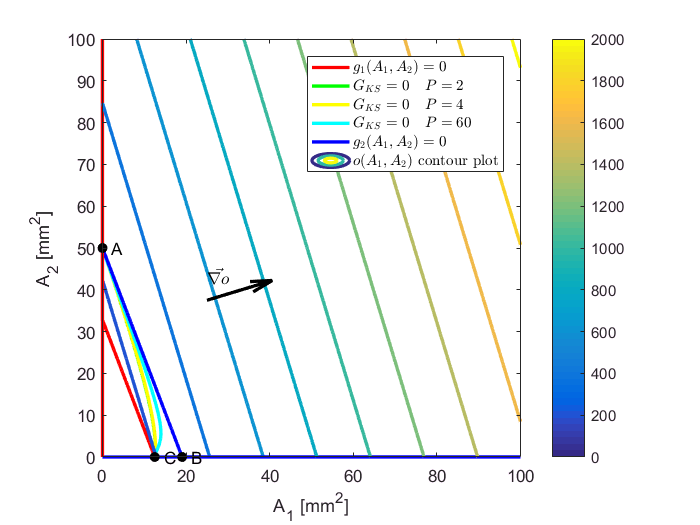

barg_1=(abs(s_1)/sl_1-1).*(A_1/100);
barg_2=(abs(s_2)/sl_2-1).*(A_2/100);
P=2;
G_ks_2=1/P*log(1/2*(exp(P*(barg_1))+exp(P*(barg_2))));
P=4;
G_ks_4=1/P*log(1/2*(exp(P*(barg_1))+exp(P*(barg_2))));
P=60;
G_ks_6=1/P*log(1/2*(exp(P*(barg_1))+exp(P*(barg_2))));
figure
contour(A_1,A_2,g_1,[0 0],'r','LineWidth',2)
hold on
contour(A_1,A_2,G_ks_2,[0 0],'g','LineWidth',2)
contour(A_1,A_2,G_ks_4,[0 0],'y','LineWidth',2)
contour(A_1,A_2,G_ks_6,[0 0],'c','LineWidth',2)
contour(A_1,A_2,g_2,[0 0],'b','LineWidth',2)
contour(A_1,A_2,o,'LineWidth',2) 
colorbar
xlabel('A_1 [mm^2]')
ylabel('A_2 [mm^2]')
legend({'$g_1(A_1,A_2)=0$','$G_{KS}=0 \quad P=2$','$G_{KS}=0 \quad P=4$'...
    ,'$G_{KS}=0 \quad P=60$','$g_2(A_1,A_2)=0$','$o(A_1,A_2)$ contour plot'}...
    ,'Interpreter','latex')
plot([0,50],[0,0],'b','LineWidth',2)
plot([0,0],[0,75],'r','LineWidth',2)
scatter(0,a,'filled','k')
scatter(b,0,'filled','k')
scatter(c,0,'filled','k')
text(0,a,'  A')
text(b,0,'  B')
text(c,0,'  C')
quiver(25,75/2,rho_1*L_1,rho_2*L_2,0,'k','LineWidth',2,'MaxHeadSize',1)
axis equal
text(25,75/2+5,'$\vec{\nabla o}$','Interpreter','latex')

Finally solve the optimization problem for each value of P of the KS function. What can we conclude?

We can use the same stress constraint with $\epsilon =0$.

[xmin_P2]=fmincon(@(x) mass_truss(x),[35,35],[],[],[],[],[0 0],[50 75]...

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    7.113750e+02    0.000e+00    1.558e+01
    1       6    4.482205e+02    0.000e+00    1.551e+01    1.614e+01
    2       9    1.972107e+02    3.691e-02    1.526e+01    1.540e+01
    3      13    1.970467e+02    3.705e-02    7.550e+00    1.068e-02
    4      16    2.201953e+02    1.718e-02    2.473e+00    1.492e+00
    5      19    2.413419e+02    1.016e-03    1.800e-01    1.828e+00
    6      22    2.425435e+02    1.863e-05    2.604e-01    1.108e+00
    7      25    2.379859e+02    0.000e+00    7.019e+00    2.099e+01
    8      28    2.284395e+02    0.000e+00    8.583e+00    3.757e+00
    9      31    2.275486e+02    0.000e+00    8.588e+00    5.473e-02
   10      34    1.948184e+02    5.842e-05    8.438e+00    2.098e+00
   11      37    1.947685e+02    7.428e-05    9.811e-04    3.181e-03
   12      40    1.950001e+02    0.000e+00    4

xmin_P2 =    12.5000    0.0000


    ,@(x) aggregated_relaxed_unified_stress_constraints(x,2),options)
[xmin_P4]=fmincon(@(x) mass_truss(x),[35,35],[],[],[],[],[0 0],[50 75]...

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    7.113750e+02    0.000e+00    1.558e+01
    1       6    4.482155e+02    0.000e+00    1.551e+01    1.614e+01
    2       9    1.954836e+02    4.034e-02    1.526e+01    1.551e+01
    3      13    1.953526e+02    4.046e-02    7.533e+00    8.929e-03
    4      16    2.183978e+02    1.948e-02    2.625e+00    1.581e+00
    5      19    2.411036e+02    1.568e-03    2.097e-01    2.522e+00
    6      22    2.427694e+02    2.395e-05    4.001e-01    2.200e+00
    7      25    2.359259e+02    0.000e+00    8.703e+00    2.259e+01
    8      28    2.354864e+02    0.000e+00    8.748e+00    1.088e-01
    9      31    1.941056e+02    2.883e-04    8.364e+00    2.653e+00
   10      34    1.939181e+02    3.482e-04    3.940e-01    1.198e-02
   11      37    1.949995e+02    1.969e-07    4.898e-03    6.947e-02
   12      40    1.950004e+02    0.000e+00    4

xmin_P4 =    12.5000    0.0000


    ,@(x) aggregated_relaxed_unified_stress_constraints(x,4),options)
[xmin_P6]=fmincon(@(x) mass_truss(x),[35,35],[],[],[],[],[0 0],[50 75]...

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    7.113750e+02    0.000e+00    1.558e+01
    1       6    4.481461e+02    0.000e+00    1.552e+01    1.615e+01
    2       9    1.711400e+02    1.079e-01    1.520e+01    1.699e+01
    3      13    1.713772e+02    1.074e-01    1.019e+01    1.734e-02
    4      16    1.918777e+02    6.356e-02    8.271e+00    6.046e+00
    5      19    1.820894e+02    4.824e-03    1.218e+01    2.069e+01
    6      23    1.820008e+02    4.770e-03    7.717e+00    5.080e-02
    7      26    1.885367e+02    2.200e-03    6.195e-01    4.370e-01
    8      29    1.946788e+02    1.114e-04    2.820e-01    3.927e-01
    9      32    1.949915e+02    2.763e-06    6.782e-03    2.147e-02
   10      35    1.950004e+02    0.000e+00    1.016e-04    5.668e-04
   11      38    1.950000e+02    0.000e+00    2.176e-05    3.301e-05
   12      41    1.950000e+02    0.000e+00    3

xmin_P6 =    12.5000    0.0000


    ,@(x) aggregated_relaxed_unified_stress_constraints(x,60),options)

The global optimum is found in for any value of P. Changing the initial guess we can also fall into a second local minimum closer to A.

**1 Bonus) add the gradient constraints.**

**Solution**

Since relaxed and aggregated constraint belongs to $\mathbf{C}^\infty$ their gradient can be evaluated for each couple of value $(A_1,A_2)$:


$$\frac{dG_{KS}}{dA_j}=\frac{\sum_{i=1}^{N}\frac{d\bar{g}_i}{dA_j}e^{P\bar{g}_i}}{\sum_{i=1}^{N}e^{P\bar{g}_i}}=\frac{\sum_{i=1}^{N}\left( \frac{\delta_{i,j}g_i}{\max(A_i)}+\frac{A_i}{\max(A_i)}\frac{dg_i}{dA_j}\right)e^{P\bar{g}_i}}{\sum_{i=1}^{N}e^{P\bar{g}_i}}$$


options = optimoptions('fmincon','Display','iter'...
    ,'SpecifyObjectiveGradient',true,'SpecifyConstraintGradient',true,'CheckGradients',true);
[xmin]=fmincon(@(x) mass_truss(x),[35,35],[],[],[],[],[0 0],[50 75]...

____________________________________________________________
   CheckGradients Information

Objective function derivatives:
Maximum relative difference between supplied 
and finite-difference derivatives = 8.35597e-09.

Nonlinear inequality constraint derivatives:
Maximum relative difference between supplied 
and finite-difference derivatives = 2.04993e-10.

CheckGradients successfully passed.
____________________________________________________________

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.113750e+02    0.000e+00    1.558e+01
    1       2    4.481461e+02    0.000e+00    1.552e+01    1.615e+01
    2       3    1.711400e+02    1.079e-01    1.520e+01    1.699e+01
    3       5    1.713772e+02    1.074e-01    1.019e+01    1.734e-02
    4       6    1.918777e+02    6.356e-02    8.270e+00    6.046e+00
    5       7    1.820901e+02    4.824e-03    1.218e+01    2.069e+01
  

xmin =    12.5000    0.0000


    ,@(x) aggregated_relaxed_unified_stress_constraints(x,60),options)

The global minimum is found in just 15 function calls instead of 41.

## References

[1] Verbart, Alexander, Matthijs Langelaar, and Fred Van Keulen. "A unified aggregation and relaxation approach for stress-constrained topology optimization." *Structural and Multidisciplinary Optimization* 55.2 (2017): 663-679.

[2] Coniglio, Simone, et al. "Original Pylon Architecture Design Using 3D HPC Topology Optimization." *2018 AIAA/ASCE/AHS/ASC Structures, Structural Dynamics, and Materials Conference*. 2018.

[3] Cheng, G. D., and Xiao Guo. "ε-relaxed approach in structural topology optimization." *Structural optimization*13.4 (1997): 258-266

 [4] Kreisselmeier, G., and R. Steinhauser. "Systematic control design by optimizing a vector performance index." *Computer aided design of control systems*. 1980. 113-117.